
[x]=importdata('listx.txt');

[y]=importdata('listy.txt');

[z]=importdata('listz.txt');

%{
latGRID=38.9981236:0.00018:39.0170591;
lonGRID=-0.1767568992:0.00023:-0.1454121450;

[LATGRID,LONGRID]=meshgrid(latGRID,lonGRID)d
%}
% 39.016102, -0.204320
% 38.979311, -0.133220
y1 = 38.979311:(0.00018*5):39.016102; 
x1= -0.204320:(0.00023*5):-0.133220;


[X1,Y1] = meshgrid(x1,y1);

writematrix(X1,"fixedx.txt",'Delimiter',',') 
writematrix(Y1,"fixedy.txt",'Delimiter',',') 

Z_corrector= griddata(x,y,z,X1,Y1,'cubic');

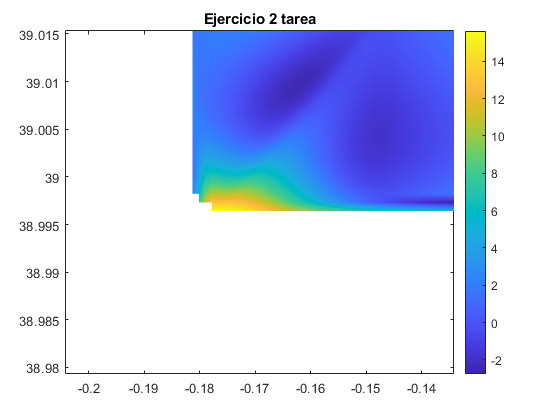

 pcolor(X1,Y1,Z_corrector), shading interp, colorbar
% plot(Z_corrector)
title('Ejercicio 2 tarea')


% figure, [C,h]=contour(X1,Y1,LDEN_corrector, 30); clabel(C,h),colorbar
% title('Curvas de nivel tarea 2')
writematrix(Z_corrector,'result.txt','Delimiter',',')  
